# Plot Sensitivities

- Load the symbolic char parameters and the sensitivities to plot

- Make algorithm that allows for easy focus on specific DOF->Muscles

- Plot Sensitivities

#### Step 1: Load the symbolic char parameters and the sensitivities to plot

clear;
clear all;

% Load params and sensitivities
Parameters;
load("AIE_Means.mat", "AIE_Means");
load("SIE_Means.mat", "SIE_Means");
load("AIE_Sensitivities.mat", "AIE_Sensitivities");
load("SIE_Sensitivities.mat", "SIE_Sensitivities");


#### Step 2: Make algorithm that allows for easy focus on specific DOF->Muscles

dofs = {'SFE', 'SAA', 'SIER', 'EFE', 'FPS', 'WFE', 'WRUD'};
muscles = {'DELT1', 'DELT2', 'DELT3', 'PECM2', 'BIClong', 'BICshort', 'TRIlong', 'TRIlat', 'BRA', 'BRD', 'PT', 'FCR', 'FCU', 'ECR', 'ECU'};

% Combine dofs with muscles (15x7 = 105)
for dof = 1:length(dofs)
    for muscle = 1:length(muscles)
        dof_to_muscles(dof, muscle) = dofs(dof) + "->" + muscles(muscle);
    end
end

% Get location of desired dof to muscles; change accordingly
dof = 'SAA';
muscle = 'DELT1';

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
keyword = dof + "->" + muscle; % DO NOT CHANGE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% These are the locations to be acquired
dof_loc = 1;
muscle_loc = 0;

for d = 1:size(dof_to_muscles, 1)
    for m = 1:size(dof_to_muscles, 2)
        if keyword == dof_to_muscles(d, m)
            dof_loc = d;
            muscle_loc = m;
        end
    end
end

#### Step 3: Plot Sensitivities

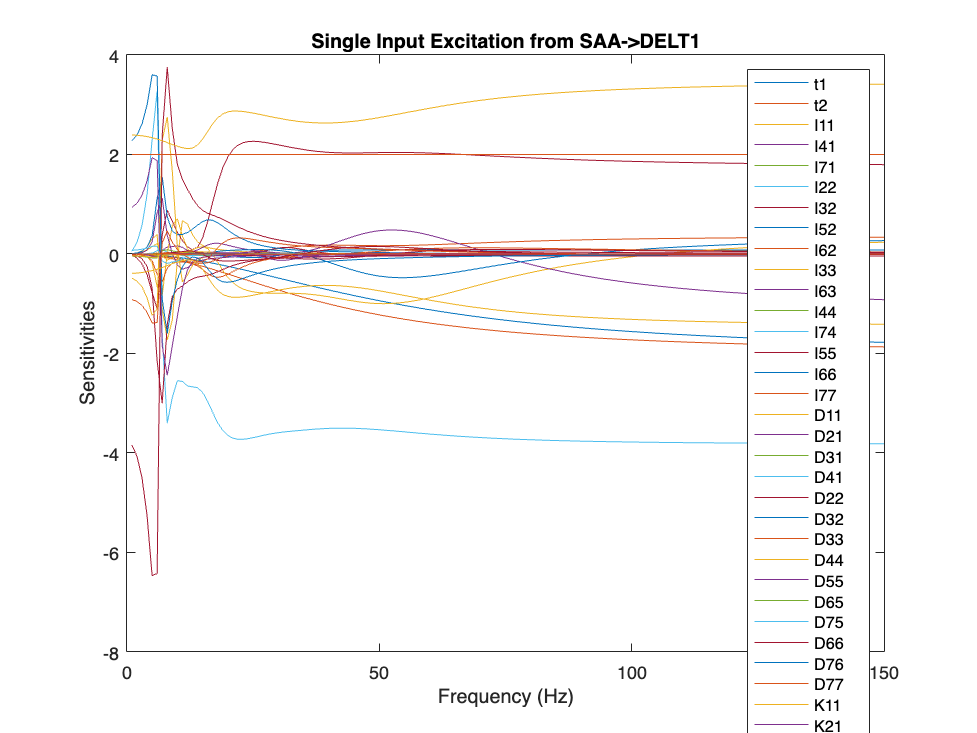

% Let's first plot Single Input Sensitivites with their mean, where tremor
% band is at [4, 8]Hz

SIE_Plot(SIE_Sensitivities, dof_loc, muscle_loc, params_char, dof_to_muscles);

AIE_Plot(AIE_Sensitivities, params_char);

% Now, let's do the means
figure;

% SIE_Means heat map
for s = 1:length(SIE_Means)
    s_h = heatmap(SIE_Means{s});
end
